# Linear Inverse Model - Bering Sea Ice

This live script is the principal workflow for a publication in-prep, Cox and Penland (2025).

**Objective:** Build a linear inverse model (LIM) to evaluate the predictibility of wind-forced expansion and retreat of the wintertime Bering Sea ice edge.

**Purpose:** Benchmark expectations for minimum skill of NOAA's fully-coupled UFS-Arctic system, currently in development.

**Timescales of interest: **Synoptic to subseasonal scales, mostly 48 hours  to 3 weeks. Current Navy requirements for U.S. National Ice Center are 48-hour forecasts, which are issued by analysists.

**Code Dependencies: **

Developed in MATLAB R2024b, but should be backward compatable to ~R2019b

C. Cox's lim_codes (this repo), [https://github.com/chrisjcox/lim-codes](https://github.com/chrisjcox/lim-codes) 

C. Cox's development fork of the Torrence and Compo (1998) wavelet codes, [https://github.com/chrisjcox/wavelets/tree/develop](https://github.com/chrisjcox/wavelets/tree/develop) 

Colorbrewer for colormaps. The exact code is depreciated, I think, so I suggest replacing cbrewer.m calls with your preference.

The final section uses m_map, [https://www-old.eoas.ubc.ca/~rich/map.html](https://www-old.eoas.ubc.ca/~rich/map.html) 

**References:**

Cox, C.J. and C. Penland (2025) Medium-range predictability of the wintertime Bering Sea ice edge using Linear Inverse Modeling. to be submitted, *Journal of Geophysical Research - Oceans*.

Torrence, C. and G.P. Compo (1998) A practical guide to wavelets. Bulletin of the American Meteorological Society, 79, 61-78. [https://doi.org/101175/1520-0477(1998)079<0061:APGTWA>2.0.CO;2](https://doi.org/101175/1520-0477(1998)079%3C0061:APGTWA%3E2.0.CO;2)  

____________________________________________________________________________________________________________________________________________________________________________________________________

### I. Options and Loading

The primary data is the 25x25 km sea ice index based on SSM/I&SSMIS satellite sensors produced by the National Snow and Ice Data Center (NSIDC). We use Sea Ice Index (SII) v3 (Fetterer et al., 2017). SII begins 26 October 1978, but it is provided only every 2 days until 13 January 1988. Here we will select the period of continuous daily granularity.

LIM "stations" for the present model are meridians of longitude. Valid selections are 180°E  to 200°E. We have preselected 181°E  to 198°E for reseason described in the manuscript, though the we show the work ahead of time and don't subset until Section IV.

The Aleutian Low Beaufort Sea Anticyclone (ALBSA) is a daily index of 850 hPa geopotential height that is sensitive to the juxtaposition of the Aleutian Low and the Beaufort High. It captures the regional atmospheric dynamical patters we hypothesize to be important to the tendencies of the wind forcing on the sea ice. See Cox et al. (2019).

**New References:**

Cox, C. J., Stone, R. S., Douglas, D. C., Stanitski, D. M., and Gallagher, M. R. (2019) The Aleutian Low – Beaufort Sea Anticyclone: A climate index correlated with the timing of springtime melt in the Pacific Arctic. *Geophysical Research Letters*, 46(13), 7464-7473. [https://doi.org/10.1029/2019GL083306](https://doi.org/10.1029/2019GL083306) 

Fetterer, F. Knowles, K., Meier, W. N., Savoie, M., and Windnagel, A. K. (2017) Sea Ice Index (G02135, Version 3). [Dataset]. National Snow and Ice Data Center. [https://doi.org/10.7265/N5K072F8](https://doi.org/10.7265/N5K072F8)  

% Set you paths
code_path = '/Users/ccox/Documents/software/git_repos/lim-codes/'      ; % access to project mfiles
fig_path  = '/Users/ccox/Documents/Projects/2024/bering_ice/pub/figs/' ; % store figures here
data_path = '/Users/ccox/Documents/Projects/2024/bering_ice/data/'     ; % NSIDC data directory 
albsa_dir = '/Users/ccox/Documents/Projects/2024/albsa/'               ; % Location of ALBSA data

% Load NSDIC?
%   1 = Reload from file (takes a while)
%   2 = Load preprocessed matfile
load_type = 2;

% Save Figures?
%   1 = Save 
%   2 = Skip
sav_fig = 2;

% Set meridians [degrees longitude]
stas = 175:200; 

% Begin and end dates of NSIDC data.
date_beg = datenum([1988 1 13 0 0 0]);
date_end = datenum([2025 4 29 0 0 0]);

% De-seasonalizing options
% deseas 
%   = 1 remove 1st component
%   = 2 remove 1st, 2nd components
%   = 3 remove 1st, 2nd, 3rd  components
deseas = 2;

% What months are included in the analysis?
mo_inc = 1:3;

% Data Split, training and validation sets
train_years = 1988:2018;
validation_years = 2019:2025;

% Access some stuff
addpath(code_path); 
load([data_path,'nsidc_data']);

% Subset period of analysis
ibeg = find(iceedge_dn == date_beg);
iend = find(iceedge_dn == date_end);
iceedge = iceedge(:,ibeg:iend);
iceedge_dn = iceedge_dn(ibeg:iend);

% Date info
[yyyy,mm,dd,~,~,~] = datevec(iceedge_dn); % year, month, day
iceedge_doy = iceedge_dn-datenum([yyyy;yyyy.*0+1;yyyy.*0;yyyy.*0;yyyy.*0;yyyy.*0]')'; % day of year

% Collect indexes for training and validation sets
train_inds = find(ismember(yyyy,train_years));
validation_inds = find(ismember(yyyy,validation_years));

% Loads daily ALBSA index values (Cox et al., 2019)
% - Resamples to the NSDIC time series, removes April-December.
load([albsa_dir,'albsadailynew.mat']);
i_resamp = find(ismember(albsa.dn,iceedge_dn));
albsalim = albsa.i(i_resamp); albsalim(~ismember(mm,mo_inc)) = NaN;
amap = albsa.map(:,:,i_resamp); amap(:,:,~ismember(mm,mo_inc)) = NaN;

% Number of "stations", which for this LIM are longitudes. This is ALL possible station (170-200)
nDato = size(iceedge,1);

### II. De-seasonalizing and outlier removal

This analysis will focus on variability at timescales smaller than the seasonal cycle, as well as contributions from interannual variablity in the first three components of the seasonal cycle. At the pan-Arctic scale, Lopes et al. (2023) showed that the first three components of the seasonal cycle in the sea ice extent are all signficant, representing 95.6%, 2.69%, and 0.43% of the variance. The remaining 1.3% was considered residual "noise". We will explore the predctability of this "noise", given the hypothesis that persistence from the polar jet (as expressed by ALBSA) results in mean tendencies for on- or off-ice floe a 1-2 weeks (Cox et al. 2019). We will also repeat the analysis being inclusive of component three, and again with components two and three. Therefore, we define the seasonal cycle continously, not climatological (it varies interannually). We use a wavelet deseasonalizing method (e.g., Szolgayová et al., 2014). Specfically, we reconstruct the seasonal cycle time series from the transform using pre-defined thresholds defined by the seasonal harmonic periods and adjusted for the Fourier period of the wavelet.

The wavelet procedure is Torrence and Compo (1998). Output printed to screen is produced by wavelet.m, called by the waveletwrapper. The output refers to closure equations that firstly provide a check that a sufficiently large po2 was selected for reconstruction (of the full time series) and secondly that the reconstruction accuracy is acceptable. Past work has suggested that reconstructions should have losses < 2% (Cox et al., 2014), which we achieve here.

**New References:**

Cox, C.J., V.P. Walden, G.P. Compo, P.M. Rowe, M.D. Shupe, and K. Steffen (2014) Downwelling longwave flux over Summit, Greenland, 2010-2012: Analysis of surface-based observations and evaluation of ERA-Interim using wavelets. *Journal of Geophysical Research - Atmospheres*, 119, 12317-12337. [https://doi.org/10.1002/2014JD021975](https://doi.org/10.1002/2014JD021975) 

Lopes, F., Couterillot, V., Gibert, D., and Le Mouël, J.-L. (2023) On the annual and semi-annual components of variations in extent of Arctic and Antarctic sea-ice. *Geosciences*, 13, 21. [https://doi.org/10.3390/geosciences13010021](https://doi.org/10.3390/geosciences13010021)  

Szolgayová, E., Arlt, J., Blöschl, G., and Szolgay, J. (2014) Wavelet based deseasonalization for modelling and forecasting of daily discharge series considering long range dependence. *Journal of Hydrology and Hydromechanics*, 62, 24-32. [https://doi.org/10.2478/johh-2014-0011](https://doi.org/10.2478/johh-2014-0011)   

iceedgedt = iceedge; % dt is the de-seasonalized time series
seas = []; % store the season time series
ndspk = 0; % de-spiking counter
gooddata = NaN(1,nDato);
for k = 1:nDato
    
    fprintf(['Deseasonalizing Meridian = ',num2str(stas(k)),'\n'])

    % Assign vector, interpolating over nans
    merid_k = iceedge(k,:);
    merid_k_nonan = interp1( iceedge_dn(~isnan(merid_k)), merid_k(~isnan(merid_k)) , iceedge_dn, 'linear', 'extrap');

    % first despike by comparison to a 10-day running mean
    y1 = movmean(merid_k_nonan,10);
    tmp = iceedge(k,:)-y1;
    ibad = find(abs(tmp) > std(tmp)*8);
    ndspk = ndspk + length(ibad);
    iceedge(k,ibad) = NaN;
    gooddata(k) = length(find(~isnan(iceedge(k,mm<=3))));
    
    % fill gaps. this is just for fitting the seasonal cycle
    % have tried also gap filling with neighboring stations and climatology, but this has little effect
    merid_k = iceedge(k,:);
    merid_k_nonan = interp1( iceedge_dn(~isnan(merid_k)), merid_k(~isnan(merid_k)) , iceedge_dn, 'linear', 'extrap');

    % then deseasonalize
    data = waveletwrapper(merid_k_nonan,iceedge_dn);

    % the equivalent Fourier period of the wavelet (Table 1, T&C1998)
    lambda = (4*pi*data.period) / (6 + sqrt(2+6^2)); 

    % now filter:
    if deseas == 1
        ind = find(lambda  > exp((log(365/1)+log(365/2))/2)); % remove 1st component
    elseif deseas == 2
        ind = find(lambda  > exp((log(365/2)+log(365/3))/2)); % remove 1st, 2nd components
    elseif deseas == 3
        ind = find(data.period > exp((log(365/3)+log(365/4))/2)); % remove 1st, 2nd, 3rd  components
    end
   
    y1 = sum(data.x(:,ind),2) + mean(naninterp(iceedge(k,:)),'omitnan');
    seas = [seas; y1'];
    iceedgedt(k,:) = iceedge(k,:)-y1';
end

Deseasonalizing Meridian = 175


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.032655 units.
The variance closure from Eq.[14] (1:N) is 98.7453%.
The variance closure from Eq.[11] (1:n) is 100.6084%.
The variance from Eq.[14 (1:N) is 14.017


Deseasonalizing Meridian = 176


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.02206 units.
The variance closure from Eq.[14] (1:N) is 98.7523%.
The variance closure from Eq.[11] (1:n) is 100.6238%.
The variance from Eq.[14 (1:N) is 13.061


Deseasonalizing Meridian = 177


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.031965 units.
The variance closure from Eq.[14] (1:N) is 98.7449%.
The variance closure from Eq.[11] (1:n) is 100.6087%.
The variance from Eq.[14 (1:N) is 12.9529


Deseasonalizing Meridian = 178


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.024142 units.
The variance closure from Eq.[14] (1:N) is 98.7508%.
The variance closure from Eq.[11] (1:n) is 100.6215%.
The variance from Eq.[14 (1:N) is 12.7761


Deseasonalizing Meridian = 179


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.027229 units.
The variance closure from Eq.[14] (1:N) is 98.7487%.
The variance closure from Eq.[11] (1:n) is 100.6169%.
The variance from Eq.[14 (1:N) is 12.881


Deseasonalizing Meridian = 180


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.03131 units.
The variance closure from Eq.[14] (1:N) is 98.7454%.
The variance closure from Eq.[11] (1:n) is 100.6091%.
The variance from Eq.[14 (1:N) is 13.0383


Deseasonalizing Meridian = 181


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.027734 units.
The variance closure from Eq.[14] (1:N) is 98.7485%.
The variance closure from Eq.[11] (1:n) is 100.6156%.
The variance from Eq.[14 (1:N) is 13.2679


Deseasonalizing Meridian = 182


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.039417 units.
The variance closure from Eq.[14] (1:N) is 98.7372%.
The variance closure from Eq.[11] (1:n) is 100.5918%.
The variance from Eq.[14 (1:N) is 12.7728


Deseasonalizing Meridian = 183


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.029524 units.
The variance closure from Eq.[14] (1:N) is 98.7474%.
The variance closure from Eq.[11] (1:n) is 100.6139%.
The variance from Eq.[14 (1:N) is 13.4375


Deseasonalizing Meridian = 184


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.039597 units.
The variance closure from Eq.[14] (1:N) is 98.739%.
The variance closure from Eq.[11] (1:n) is 100.5975%.
The variance from Eq.[14 (1:N) is 13.7929


Deseasonalizing Meridian = 185


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.042821 units.
The variance closure from Eq.[14] (1:N) is 98.7364%.
The variance closure from Eq.[11] (1:n) is 100.589%.
The variance from Eq.[14 (1:N) is 14.5888


Deseasonalizing Meridian = 186


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.032887 units.
The variance closure from Eq.[14] (1:N) is 98.7465%.
The variance closure from Eq.[11] (1:n) is 100.6117%.
The variance from Eq.[14 (1:N) is 15.4783


Deseasonalizing Meridian = 187


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.026374 units.
The variance closure from Eq.[14] (1:N) is 98.7514%.
The variance closure from Eq.[11] (1:n) is 100.6223%.
The variance from Eq.[14 (1:N) is 16.4569


Deseasonalizing Meridian = 188


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.03334 units.
The variance closure from Eq.[14] (1:N) is 98.7473%.
The variance closure from Eq.[11] (1:n) is 100.6134%.
The variance from Eq.[14 (1:N) is 17.0349


Deseasonalizing Meridian = 189


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.046635 units.
The variance closure from Eq.[14] (1:N) is 98.7366%.
The variance closure from Eq.[11] (1:n) is 100.5884%.
The variance from Eq.[14 (1:N) is 17.5429


Deseasonalizing Meridian = 190


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.03448 units.
The variance closure from Eq.[14] (1:N) is 98.7471%.
The variance closure from Eq.[11] (1:n) is 100.6123%.
The variance from Eq.[14 (1:N) is 17.9971


Deseasonalizing Meridian = 191


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.042151 units.
The variance closure from Eq.[14] (1:N) is 98.7422%.
The variance closure from Eq.[11] (1:n) is 100.6017%.
The variance from Eq.[14 (1:N) is 19.0246


Deseasonalizing Meridian = 192


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.046477 units.
The variance closure from Eq.[14] (1:N) is 98.7395%.
The variance closure from Eq.[11] (1:n) is 100.5961%.
The variance from Eq.[14 (1:N) is 19.9772


Deseasonalizing Meridian = 193


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.046603 units.
The variance closure from Eq.[14] (1:N) is 98.7402%.
The variance closure from Eq.[11] (1:n) is 100.5964%.
The variance from Eq.[14 (1:N) is 20.8226


Deseasonalizing Meridian = 194


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.043517 units.
The variance closure from Eq.[14] (1:N) is 98.7429%.
The variance closure from Eq.[11] (1:n) is 100.6026%.
The variance from Eq.[14 (1:N) is 21.2754


Deseasonalizing Meridian = 195


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.037631 units.
The variance closure from Eq.[14] (1:N) is 98.7473%.
The variance closure from Eq.[11] (1:n) is 100.613%.
The variance from Eq.[14 (1:N) is 21.7393


Deseasonalizing Meridian = 196


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.049412 units.
The variance closure from Eq.[14] (1:N) is 98.7394%.
The variance closure from Eq.[11] (1:n) is 100.5948%.
The variance from Eq.[14 (1:N) is 22.5336


Deseasonalizing Meridian = 197


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.036728 units.
The variance closure from Eq.[14] (1:N) is 98.7482%.
The variance closure from Eq.[11] (1:n) is 100.6148%.
The variance from Eq.[14 (1:N) is 22.606


Deseasonalizing Meridian = 198


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.045073 units.
The variance closure from Eq.[14] (1:N) is 98.7428%.
The variance closure from Eq.[11] (1:n) is 100.6032%.
The variance from Eq.[14 (1:N) is 22.6315


Deseasonalizing Meridian = 199


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.033099 units.
The variance closure from Eq.[14] (1:N) is 98.7499%.
The variance closure from Eq.[11] (1:n) is 100.6176%.
The variance from Eq.[14 (1:N) is 21.9798


Deseasonalizing Meridian = 200


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.025813 units.
The variance closure from Eq.[14] (1:N) is 98.7535%.
The variance closure from Eq.[11] (1:n) is 100.6271%.
The variance from Eq.[14 (1:N) is 21.8918


% We are interested in wintertime data, though the seasonal cycle is, in
% practice, most easily separable for JFM. Therefore, we set all other
% months, April-December, to NaN.
iceedgedt(:,~ismember(mm,mo_inc))=NaN;

% despike again, this time by year
yyyyu = unique(yyyy);
for k = 1:length(yyyyu)
    ind = find(yyyy == yyyyu(k));
    a1 = [iceedgedt(:,ind)'-mean(iceedgedt(:,ind),'omitnan')']';
    a2 = reshape(a1,size(a1,1)*size(a1,2),1);
    ind2 = find(abs(a2) > std(a2,'omitnan').*5);
    ndspk = ndspk + length(ind2);
    tmp = iceedgedt(:,ind);
    tmp(ind2) = NaN;
    iceedgedt(:,ind) = tmp;
end

disp(['Despiking removed ', num2str(ndspk ./ (length(find(~isnan(iceedgedt)))+ndspk) * 100),'%']);

Despiking removed 0.12972%


### III. Subset stations

So far, we have been inclusive of all meridians between 175° and 200° E, as were selected by Wohl (1991). However, meridians near the edges of the domain have less data and less variance. They may not be very representative of the dynamics and could inflate the calculated skill. This section shows how we came up with the subset 181° and 198° E.

**New References:**

Wohl, G.M. (1991) Sea ice edge forecast verifcation program for the Bering Sea. *National Weather Digest*, 16(4), 6-12.

% Calculate the variance and "uptime" for each station
nlags = 90;
sta_uptime = NaN(nDato,90)       ; % fraction of time the station has valid data, JFM
sta_var    = NaN(nDato,1)        ; % variance of the station distribution, JFM
sta_af     = NaN(nDato,nlags+1)  ; % station autocorrelation function, JFM
sta_eF     = NaN(nDato,1)        ; % station eFolding time based on sta_af
for h = 1:nDato

    % calculate variance of the station
    sta_var(h) = var(iceedgedt(h,:),'omitnan');

    % calculate the autocorrelation function, save it
    % calculate the eFolding time from the AF
    datatmp = iceedgedt(h,:);
    output = [0:nlags].*NaN;
    for q = 0:nlags
        if q == 0
            output(h+1) = 1;
        else
            x = transpose(datatmp(1:end-q)) - mean(datatmp,'omitnan');
            y = transpose(datatmp(q+1:end)) - mean(datatmp,'omitnan');
            [xx pp] = nancorrcoef(x,y);
            if length(xx) > 1
                output(q+1) = xx(2);
            end
        end
    end
    output(1)=1;
    sta_af(h,:) = output; 
    nl2 = 0:0.01:nlags;
    highres = interp1(0:nlags,output,nl2);
    sta_eF(h) = nl2(find(highres < 1/exp(1),1,'first'));
    
    % calculate uptime
    for k = 1:90
        ind1 = find(iceedge_doy == k);
        sta_uptime(h,k) = length(find(~isnan(iceedgedt(h,ind1)))) / length(ind1);
    end

end

% Criteria for subsetting stations: 181-198 
stind = find(mean(sta_uptime,2,'omitnan') >= 0.75 & sta_eF <= 16 & sta_var >= 0.32); % 0.32 is ~35 km

% Save the unconsolidated values for Figure 2
ie = iceedgedt;

% Now with all the statistics compiled, subset the data and send to LIM
iceedgedt = iceedgedt(stind,:);
nDat = size(iceedgedt,1);

### IV. Figure 2a,b,c,d; Figure S2

*Figure 2:* 

(a) Autocorrelation functions for each meridian. Solid lines are merdians included in the LIM and dashed lines are those at the edge of the domain included by Wohl (1991), but not considered here; (b) Contemporaneous cross-correlations amongst the meridians; (c) lagged (𝜏 = 5 days) cross-correlations amongst the meridians; (d) difference between (b) and (c) (lagged – contemporaneous). The boxes in panels (b)-(d) surround the meridians included in the LIM.

*Figure S2:*

Frequency distribution functions of xi anomaly time series. All were deseasonalized by removing the first and second components of the seasonal cycle. Bin size is 0.1°.

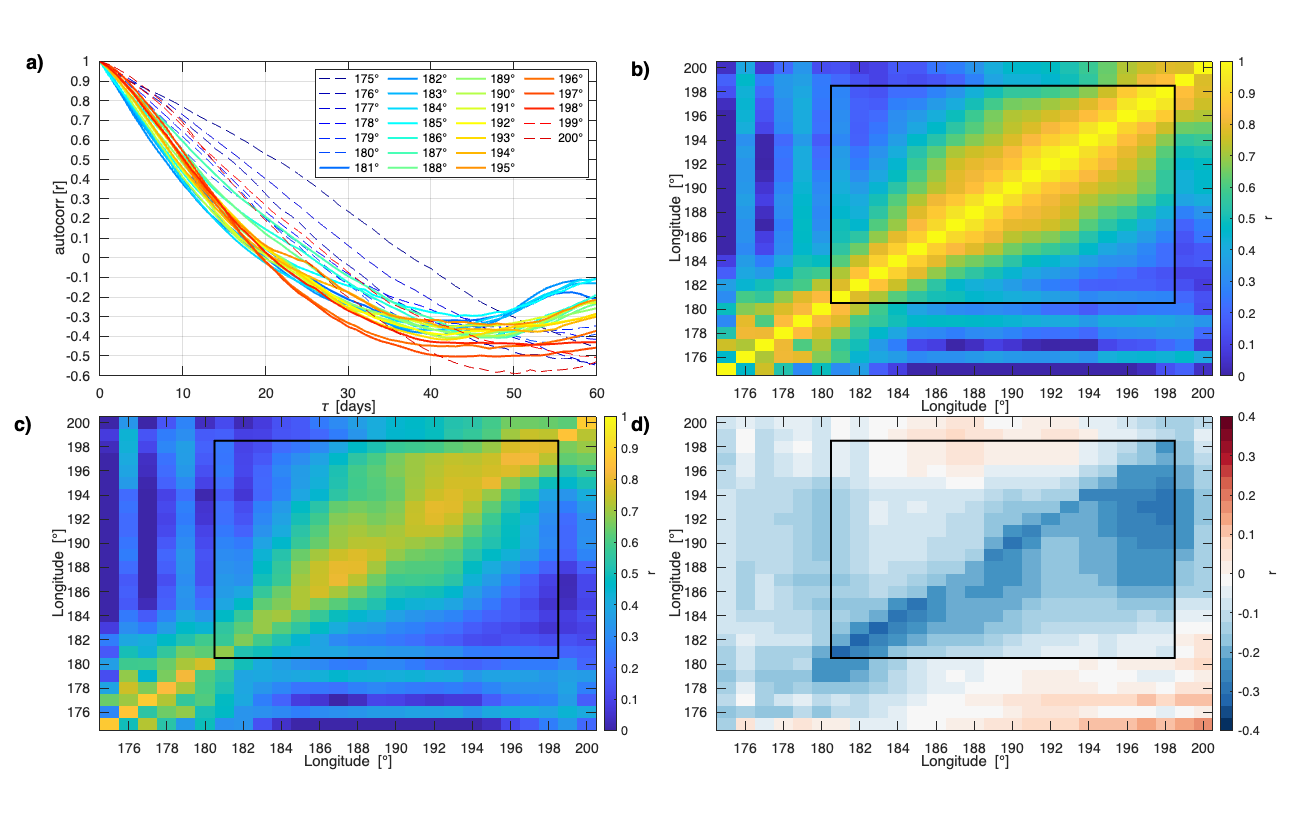

% Calculate matrices

lag = 6; % use a 6-day lag

% Figure 2b: Contemporaneous correlation matrixm, Rc
%   slopes code calculates how quickly the covariance decreases from with increasing distance from a meridian
Rc = NaN(nDato,nDato);
Rcslopes1 = NaN(nDato,nDato);
Rcslopes2 = NaN(nDato,nDato);
for k = 1:nDato
    for h = 1:nDato
        [r p] = corrcoef(ie(h,:)',ie(k,:)','Rows','pairwise');
        Rc(h,k) = r(2);
        if h >= k
            Rcslopes1(h,k) = r(2)^2;
        end
        if k > h
            Rcslopes2(h,k) = r(2)^2;
        end
    end
end
slopes = NaN(2,nDato);
for k = 1:nDato
    thex = stas;
    they = Rcslopes1(k,:);
    thex(isnan(they)) = [];
    they(isnan(they)) = [];
    if length(thex) >= 11
        tmp = polyfit(thex,they,1);
        slopes(1,k) = tmp(1);
    end
    thex = stas;
    they = Rcslopes2(k,:);
    thex(isnan(they)) = [];
    they(isnan(they)) = [];
    if length(thex) >= 11
        tmp = polyfit(thex,they,1);
        slopes(2,k) = tmp(1);
    end
end
% Figure 2b: Lagged correlation matrix
R = NaN(nDato,nDato);
for k = 1:nDato
    for h = 1:nDato
        [r p] = corrcoef(ie(h,1:end-(lag-1))',ie(k,lag:end)','Rows','pairwise');
        R(h,k) = r(2);
    end
end

% Creat a figure of the autocorrelation functions for each station.
% Save the eFolding times, we need them later for the AR1 fx.
figure('units', 'normalized', 'outerposition', [0 0 1 1]);
tiledlayout(2, 2, "TileSpacing", "tight");
cmapax1 = jet(nDato);
cmapax4 = flipud(cbrewer('div', 'RdBu',nDato, 'linear'));

ax1=nexttile;
for k = 1:nDato
    if ismember(stas(k),stas(stind))
        plot(0:nlags,sta_af(k,:),'color',cmapax1(k,:),'linewidth',2); hold on;
    else
        plot(0:nlags,sta_af(k,:),'k--','color',cmapax1(k,:),'linewidth',1); hold on;
    end
end
xlabel('\tau [days]');
ylabel('autocorr [r]');
grid on;
xlim([0 60]); ylim([-0.6 1]);
lats = stas;
set(gca,'ytick',-0.6:0.1:1,'xtick',0:10:100);
h1=legend([num2str(transpose(lats)) repmat('\circ',length(lats),1)],'location','northeast'); 
h1.FontSize = 12;
h1.NumColumns = 4;
pa=text(-9,1,'a)'); pa.FontSize=20; pa.FontWeight = 'bold';
set(gca,'fontsize',14);

ax2=nexttile;
imagesc(stas,stas,Rc); set(gca,'ydir','normal');
xlabel('Longitude [\circ]'); ylabel('Longitude [\circ]'); 
clim([0 1]); h=colorbar; h.Label.String = 'r';
colormap(parula);
rectangle('Position',[stas(stind(1))-0.5 stas(stind(1))-0.5 stas(stind(end))-stas(stind(1))+1 stas(stind(end))-stas(stind(1))+1],'linewidth',2)
set(gca,'xtick',174:2:200,'ytick',174:2:200);
colormap(ax2,'parula');
pb=text(170,200,'b)'); pb.FontSize=20; pb.FontWeight = 'bold';
set(gca,'fontsize',14);

ax3=nexttile;
imagesc(stas,stas,R); set(gca,'ydir','normal');
xlabel('Longitude [\circ]'); ylabel('Longitude [\circ]'); 
clim([0 1]); h=colorbar; h.Label.String = 'r';
colormap(parula);
rectangle('Position',[stas(stind(1))-0.5 stas(stind(1))-0.5 stas(stind(end))-stas(stind(1))+1 stas(stind(end))-stas(stind(1))+1],'linewidth',2)
set(gca,'xtick',174:2:200,'ytick',174:2:200);
colormap(ax3,'parula');
pc=text(170,200,'c)'); pc.FontSize=20; pc.FontWeight = 'bold';
set(gca,'fontsize',14);

ax4=nexttile;
imagesc(stas,stas,R-Rc); set(gca,'ydir','normal');
xlabel('Longitude [\circ]'); ylabel('Longitude [\circ]'); 
clim([-0.4 0.4]); h=colorbar; h.Label.String = 'r';
rectangle('Position',[stas(stind(1))-0.5 stas(stind(1))-0.5 stas(stind(end))-stas(stind(1))+1 stas(stind(end))-stas(stind(1))+1],'linewidth',2)
set(gca,'xtick',174:2:200,'ytick',174:2:200);
colormap(ax4,cmapax4);
pd=text(170,200,'d)'); pd.FontSize=20; pd.FontWeight = 'bold';
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 36 28]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig2.png']); end

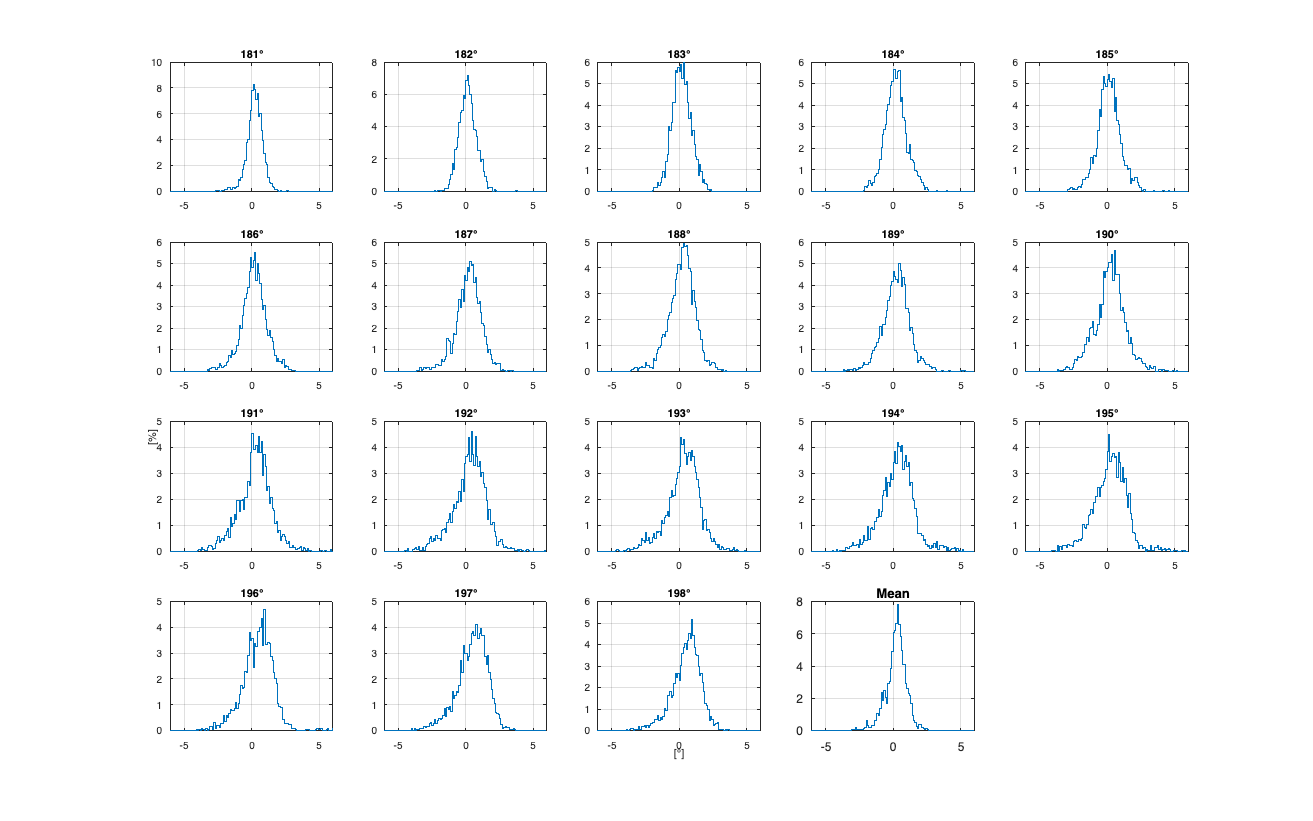


% Make the histogram supplements plot
% % See distributions of each station.
clf;
thevars = NaN(1,nDat);
for k = 1:nDat
    subplot(4,5,k);
    thevars(k) = std(iceedgedt(k,:));
    histN(iceedgedt(k,:),-15:0.1:15,'line','linewidth',1); hold on;
    title(([num2str(stas(stind(k))),'\circ']));
    set(gca,'xtick',-15:5:15); xlim([-6 6]); grid on;
    if k == nDat; xlabel('[\circ]'); end
    if k == 11; ylabel('                                [%]'); end
end
subplot(4,5,nDat+1);
histN(mean(iceedgedt(:,:)),-15:0.1:15,'line','linewidth',1);
set(gca,'xtick',-15:5:15); xlim([-6 6]); grid on; title('Mean');
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 32 16]);
set(gca,'fontsize',12); if sav_fig == 1 & deseas == 2; print('-dpng','-r300',[fig_path,'fig_S2_hists.png']); end

### V. Do LIM

The code block is a wrapper for dolim.m. LIMs are built for a series of proposed 𝜏0 (tau0_arr) for leads, 𝜏 (Tau_arr), of 1-60 days; forecasts, expected errors (espilon, ε), and diangostics (e.g., Nyquist frequency detections) are stored in arrays. We will use a tau0 = 4. The nominal criterion for selecting tau0 is that it doesn't matter! Actually, there are some guidelines. The assumed lack of dependency of results on 𝜏0 will be tested in Section VI. Let's aim for the smallest acceptable values. You cannot use a 𝜏0 >= any 𝜏 having a Nyquist frequency at stated 𝜏0 (Penland, 2019), and best perhaps to buffer that criterion too. For this application, 𝜏0 <= 3 are suspect due to the nature of the input data (see Section VI). Later, we will also discover that the observed lack of dependency of forecast skill on 𝜏0 actually corresponds to a tradeoff between the maximum amplitude of the stochastic growth and the correlation between the optimal and final structures. Nominally, this code block would choose the largest value of 𝜏0 that is -2 𝜏 from the first detected Nyquist frequency. In practice, I find that the appearance of these Nyquists is quite sensitive to even small adjustments to feature engineering of the input data (e.g., handling of outliers). The present configuration does not find any Nyquists until rather large 𝜏 so I have simply chose 𝜏0 = 4. 

There are several credits I would like to provide here, which also apply to Section VI and VII.

(1) Penland, C., M.D. Fowler, D.L. Jackson, and R. Cifelli (2021) Forecasts of opportunity in Northern California soil moisture. *Land*, 10, 713. [https://doi.org/10.3390/land10070713](https://doi.org/10.3390/land10070713) 

(2) Megan Fowler's LIM routines developed for Penland et al. (2021), [https://github.com/NOAA-PSL/Linear_Inverse_Modeling](https://github.com/NOAA-PSL/Linear_Inverse_Modeling) 

(3) Cecile Penland's *Introduction to Stochastic Processes & Linear Modeling* coursework, originally developed as a guest lecturer series at MIT.

**New References:**

Penland, C. (2019) The Nyquist issue in Linear Inverse Modeling. Monthly Weather Review, 147, 1341-1349. [https://doi.org/10.1175/MWR-D-18-104.1](https://doi.org/10.1175/MWR-D-18-104.1) 

% We will test the first 8 tau0s, each lags out to 20 days.
x = transpose(iceedgedt); % get oriented
disp(['Number of training samples = ',num2str(length(find(~isnan(x(train_inds,:)))))]);

Number of training samples = 48117


disp(['Number of validation samples = ',num2str(length(find(~isnan(x(validation_inds,:)))))]);

Number of validation samples = 10920


% fx 
tau0_arr = 1:9                                                          ; % Test these tau0s 
Tau_arr  = 1:30                                                         ; % Create array of Tau's to get error at (out to ~3 weeks)
    
fx_all           = NaN(length(tau0_arr),length(Tau_arr),nDat,length(x)) ; % Fx stored 4d array, [tau0,leadtime,station,time]
epsilon_sta      = NaN(length(tau0_arr),length(Tau_arr),nDat)           ; % Expected error per station
epsilon          = NaN(length(tau0_arr),length(Tau_arr))                ; % Expected error collectively
epsilon_raw      = NaN(length(tau0_arr),length(Tau_arr))                ; % Expected error collectively, not normalized
compL            = zeros(size(tau0_arr))                                ; % Binary, 1 = L was complex, else 0 
nyquists         = zeros(length(tau0_arr),length(Tau_arr))              ; % Binary, 1 = Nyquist frequency found
gamma1max        = zeros(length(tau0_arr),length(Tau_arr))              ; % 
firstnyq         = zeros(size(tau0_arr))                                ; % Smallest tau0 where Nyquist was found

% Run hindcasts for a series of tau0s
for iT0 = 1:length(tau0_arr)
    
    % Do LIM for this tau0
    [L,Q,B,Gtau,C0,Ctau,ualpha,valpha,galpha,tau_decay_alpha,T_mode_oscil] = dolim(x(train_inds,:),tau0_arr(iT0));
    if ~isreal(L); compL(iT0) = 1; end
   
    % Loop over lead time array (Tau_arr)
    for iTau = 1:length(Tau_arr) 

        % Check for Nyquists
        nyqtmp = abs(imag(diag(B))*(Tau_arr(iTau)));
        if any((nyqtmp>=3.138) & (nyqtmp<=3.142))
            nyquists(iT0,iTau) = 1;
        end
 
        % Define Green function at this lag 
        G_tau = real(ualpha * diag(galpha).^(Tau_arr(iTau)/tau0_arr(iT0)) * transpose(valpha));
        eps = C0-(G_tau*(C0*transpose(G_tau)));
        for k = 1:nDat
            epsilon_sta(iT0,iTau,k) =  eps(k,k) / var(x(train_inds,k),'omitnan');
        end
        epsilon(iT0,iTau) = trace(eps) / sum(var(x(train_inds,:),'omitnan'));
        epsilon_raw(iT0,iTau) = trace(eps) / nDat;
        
        % Calculate gamma
        [Psi_tmp,gamma_tmp] = eig(transpose(G_tau)*G_tau);
        gamma1max(iT0,iTau) = max(diag(gamma_tmp));
        
        fx = NaN(nDat,length(x));

        for iT = 1:length(x)-Tau_arr(iTau)    % Loop over timesteps 
        
            tmp = x(iT,:);
            ii = find(isnan(tmp));
            tmp(ii) = 0;
            thisfx = G_tau*transpose(tmp);
            thisfx(ii) = NaN;
            % Fx: compute forecast 
            fx(:,iT+Tau_arr(iTau)) = thisfx;
             
        end    

        fx_all(iT0,iTau,:,:) = fx;

    end

    tmp = find(nyquists(iT0,:) == 1,1,'first'); if isempty(tmp); tmp = 30; end
    firstnyq(iT0) = tmp;
        
end

 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 



% Pick your tau_0. We will back off two steps from the earliest Nyquist
tau_0 = find(sum(nyquists) == 1,1,'first')-2;
if isempty(tau_0); tau_0 = 4; end
tau_0 = 4; disp('You selected your own tau.');

You selected your own tau.


disp(['Selected tau0 is ',num2str(tau_0)]);

Selected tau0 is 4


% Run the code one more time using tau_0 so we have all the details.
[L,Q,B,Gtau,C0,Ctau,ualpha,valpha,galpha,tau_decay_alpha,T_mode_oscil] = dolim(x,tau_0);

 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 


## VI. Analysis of LIM diagnostics

- (1) MAC

- (2) Optimal Structure

- (3) Tau Test

**(1) Calculate the Maximum Amplification Curve (MAC)**

The MAC is calculated corresponding to each (ranked) eigenvalue (n = nDat). We are looking for peaks some lead time 𝜏 > 1 and amplitude > 1. Else, the solution to the linear system does not add information over damped persistence. The figure shows the leading eigenvalue corresponds to a significant MAC, peaking at 𝜏 = 6. 

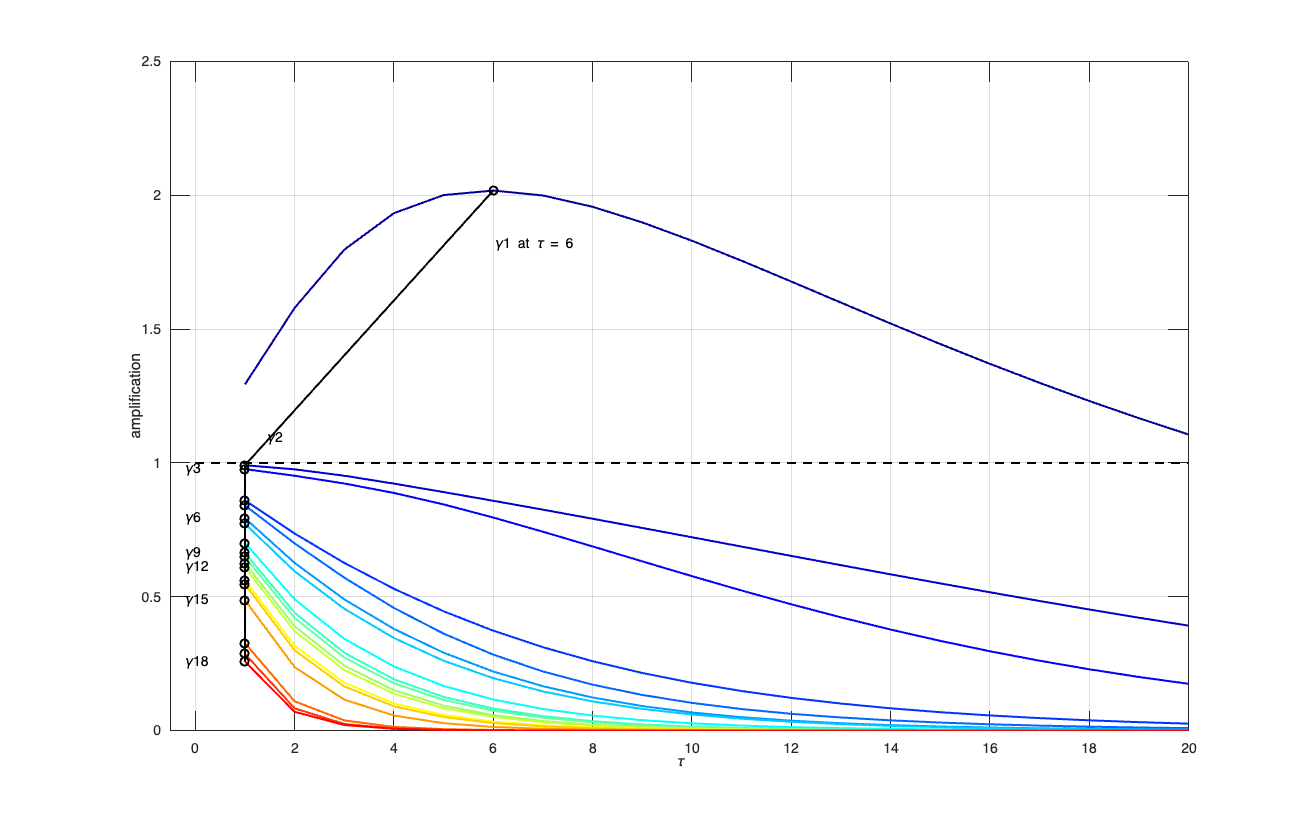

gamma1max = [];
for j = 1:max(Tau_arr)
    Gt_taum = real(ualpha * diag(galpha).^(j/tau_0) * transpose(valpha));
    [Psi1,gamma1] = eig(transpose(Gt_taum)*Gt_taum); %[EIGVEC,EIGVAL]
    gamma1 = diag(gamma1);
    if any(imag(gamma1)); break; end
    [ai,ab] = sort(gamma1,'descend');
    gamma1max = [gamma1max gamma1(ab)];
end

tau_peak = [];
peak_amp = [];
legs = [];
clf;
cmap=colormap(jet(nDat));
for k = 1:nDat
    ii = find(gamma1max(k,:) == max(gamma1max(k,:)));
    tau_peak = [tau_peak; ii];
    peak_amp = [peak_amp; gamma1max(k,ii)];
    legs = [legs; {['\gamma',num2str(k)]}];
    plot(gamma1max(k,:),'color',cmap(k,:),'linewidth',2); hold on;
end
tau_m = tau_peak(1);
plot(tau_peak,peak_amp,'ko-','linewidth',2,'markersize',8)
for ii = [1 2 3:3:nDat]% 1:length(tau_peak)
    if ii == 1
        text(tau_peak(ii),peak_amp(ii)-0.2,['\gamma',num2str(ii),' at \tau = ',num2str(tau_m)],'Color','k','fontsize',14)
    elseif ii == 2
        text(tau_peak(ii)+0.4,peak_amp(ii)+0.1,['\gamma',num2str(ii)],'Color','k','fontsize',14)
    else
        text(tau_peak(ii)-1.25,peak_amp(ii),['\gamma',num2str(ii)],'Color','k','fontsize',14)
    end
end
xlabel('\tau'); ylabel('amplification'); hline(1);
xlim([-0.5 20]); grid on;
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig_4_MAC.png']); end 

**(2) Analyze the optimal structure**

The leading eigenvalue has a peak > 𝜏 = 1 at and amplitude > 1. All other eigenvalues produce MACs that ~ <= 1 peak ampltide and generally fall off sharply after 𝜏 =1. Thus, there is only one optimal structure. This should be like saying there is a particular orientation or shape of the ice edge that is associated with high predictability due to stochasitc growth. Initial indications were that this appears when the profile of the ice edge has an anomalously meridional component to it, specifically that the ice is farther north in the west and farther south in the east. Subsequent analysis indicated that the first conclusion, i.e., that only the leading eigenvalue is significant, is robust, but that the second, i.e., a more meridional initial condition produces a more confiedent forecast, was not. Specifically, we determined that the source of the orientation-based skill was due to the 2nd and/or 3rd components of the seasonal cycle, possibly infuenced by the treatment of the time series to manage these sources of variability.

Here we plot the loading patterns. We will display values for 𝜏 = 3 to 17 to be able to assess the consistency of the structure with 𝜏, but recall that the optimal structure was determined to be at 𝜏 = 6 from the previous plot. 

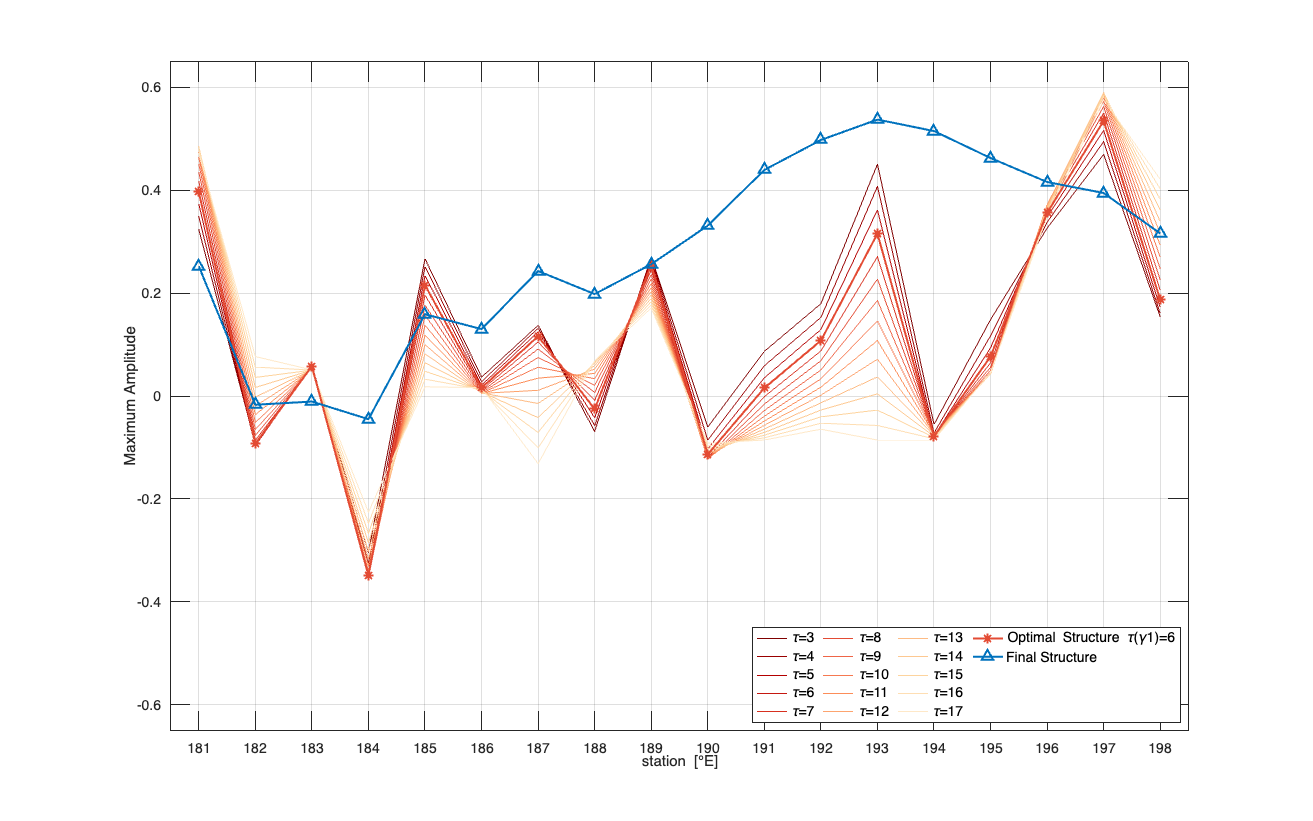

cmap2 = flipud(cbrewer('seq', 'OrRd',17, 'linear'));
cmap = lines;
h = [];
legs = [];
clf;
for k = 3:17
    tau_m_tmp = k;
    Gt_taum_tmp = real(ualpha * diag(galpha).^(tau_m_tmp/tau_0) * transpose(valpha));
    [Psi1,gamma1] = eig(transpose(Gt_taum_tmp)*Gt_taum_tmp); %[EIGVEC,EIGVAL]
    ind = find(diag(gamma1) == max(diag(gamma1)));

    optimStructtmp = real(Psi1(:,ind));
    if sign(optimStructtmp(1)) == -1
        %disp(['Optimal structure multiplied by -1 for ', 964,'m = ', num2str(k)]); % the sign is arbitrary. this step is to facilitate a cleaner figure.
        optimStructtmp = optimStructtmp.*-1;
    end

    htmp = plot(optimStructtmp,'-','color',cmap2(k-2,:),'linewidth',0.5,'markersize',10); hold on;
    h = [h; htmp];
    legs = [legs; {['\tau=',num2str(k)]}];

    if k == tau_m
        optimStruct = optimStructtmp;
        Gt_taum = Gt_taum_tmp;
    end
    
end

htmp = plot(optimStruct,'-*','color',cmap2(tau_m,:),'linewidth',2,'markersize',10); hold on; 
h = [h; htmp]; legs = [legs; {['Optimal Structure \tau(\gamma1)=',num2str(tau_m)]}];
htmp = plot(Gt_taum*optimStruct,'-^','linewidth',2,'markersize',10,'color',cmap(1,:));
h = [h; htmp]; legs = [legs; {['Final Structure']}];
xlim([0.5 length(stas(stind))+0.5]); ylim([-0.65 0.65]); grid on;
xl = stas(stind);
ylabel('Loading'); xlabel('station [\circE]'); set(gca,'xtick',1:length(stas(stind)),'xticklabel',xl(1:length(stas(stind))));
h1=legend(h,legs,'location','southeast');
h1.FontSize = 14;
h1.NumColumns = 4;
xlim([0.5 length(stas(stind))+0.5]); ylabel('Maximum Amplitude'); set(gca,'xtick',1:length(stas(stind))); %grid on;
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig3_optiStruct']); end

**(3) Conduct the "tau test"**

Figure plots the theoretical (expected) error,ε, for a series of 𝜏0 values. We will color code based on whether the 𝜏0 includes Nyquists at 𝜏 < 𝜏0 (which invalidates it) in red (if occurs) and we will plot the 𝜏0 used for the model in green. Dashed lines refer to 𝜏0 <= 3. The test is subjective: expected behavior is that ε is insensitive to the choice of 𝜏0, but the tolerance is flexible.

The test shows agreement for 𝜏0 > 3, but we consistently find some deviation for 𝜏0 <= 3. I speculate that the lower errors for 𝜏0 <= 3 days is associated with artificial smoothing of short-term variability by a combination of the coarseness of the gridded product, which is axacerbated by the regriddiing procedure, as well as the nature of the underlying data, which are temporal aggregates of a limted number of overpasses. It is probably best to avoid 𝜏0 <= 3, though the errors incurred are not expected to be large.

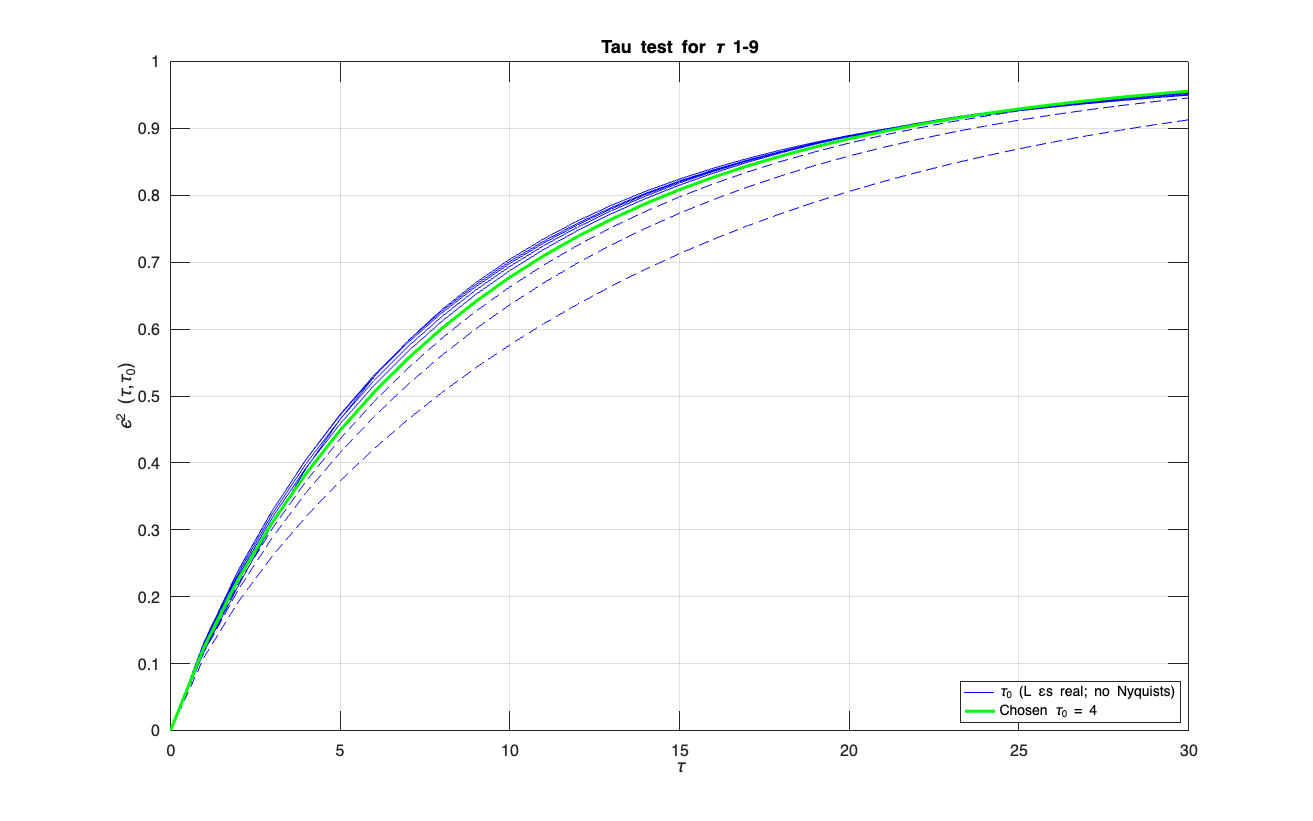

clf;
plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==0 & find(compL>-1) <= 3,1))));transpose(epsilon(compL==0 & find(compL>-1) <= 3,:))],'b--','linewidth',1); hold on;
h1=plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==0 & find(compL>-1) > 3,1))));transpose(epsilon(compL==0 & find(compL>-1) > 3,:))],'b','linewidth',1);
try
    plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==1 & find(compL>-1) <= 3,1))));transpose(epsilon(compL==1 & find(compL>-1) <= 3,:))],'r--','linewidth',1); 
end
try
    h2=plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==1 & find(compL>-1) > 3,1))));transpose(epsilon(compL==1 & find(compL>-1) > 3,:))],'r','linewidth',1);
end
h3=plot([0 Tau_arr],[transpose(zeros(size(epsilon(tau_0,1))));transpose(epsilon(tau_0,:))],'g','linewidth',3);
ylim([0 1]);
xlabel('\tau'); ylabel('\epsilon^2 (\tau,\tau_0)'); title(['Tau test for \tau ',num2str(min(tau0_arr)),'-',num2str(max(tau0_arr))]); grid on;
try
h=legend([h1(1) h2(1) h3],'\tau_0 (L is real; no Nyquists)','\tau_0 (L is complex; has Nyquists)',['Chosen \tau_0 = ',num2str(tau_0)],'location','southeast');
catch
h=legend([h1(1) h3],'\tau_0 (L εs real; no Nyquists)',['Chosen \tau_0 = ',num2str(tau_0)],'location','southeast');
end
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
set(gca,'fontsize',16); grid on; if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig_S1_tauTest.png']); end

## VII. Forecasts of opportunity

Forecasts of opportunity comprise initial conditions (IC) that are associated with particularly skillful forecasts. Skill is a distribution so a threshold is needed to classify skillful ICs. Penland et al. (2021) recommends the top tercile. Threre are two ways to idenfity the values using the LIM data:

(1) Optimal Projection: Recall that the optimal structure is the loading pattern representing the optimal IC profile for the iceedge w.r.t. predictablity. While we found that the most salient features were linked to the seasonal cycle, the optimal loading pattern can still be projected onto the ICs to isolate optimal times.

(2) Signal-to-Noise: A value, *ρ∞* (rho_infinite) may be calculated from the signal-to-noise ratio, *S*, following Newman et al. (2003), as

$\rho_{\infty } \left(t,\tau \right)=\frac{S^2 \left(t,\tau \right)}{{\left.{\left(S\right.}^2 \left(t,\tau \right)+1\right)S^2 \left(t,\tau \right)}^{0\ldotp 5} }$,

where

$S^2 \left(\tau ,t\right)=\frac{\textrm{trace}\left\lbrack f\left(\tau \right)\right\rbrack }{\textrm{trace}\left\lbrack \varepsilon \left(\tau \right)\right\rbrack }$,

where 


$$f\left(\tau \right)=\langle \hat{x} \left(\tau +1\right){\hat{x} \left(\tau +1\right)}^T \rangle \;\ldotp$$


**New References:**

Newman, M., P.D. Sardeshmukh, C.R. Winkler, and J.S. Whitaker (2003) A study of subseasonal predictability. *Monthly Weather Review*, 131, 1715-1732. [https://doi.org/10.1175//2558.1](https://doi.org/10.1175//2558.1) 

**(1) Optimal Projection**

- Use upper tercile for defining.

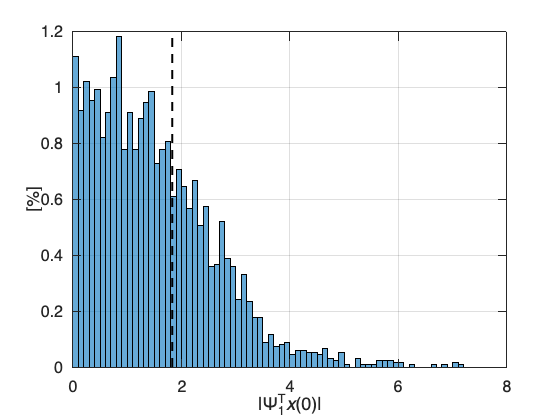

% Calculate the optimal projection from the optimal stucture in the previous section
optProj = NaN(length(x),1);
optProjF = NaN(length(x),1); 
for k = 1:length(x)-tau_m
    optProj(k) = sum(optimStruct'.*x(k,:),'omitnan'); 
    optProjF(k) = sum((Gt_taum*optimStruct)'.*x(k+tau_m,:),'omitnan'); 
end
optProj(~ismember(mm,mo_inc)) = NaN;
optProjF(~ismember(mm,mo_inc)) = NaN;

% top tercile 
indgoodfx_optprj = find(abs(optProj) > prctile(abs(optProj),66.66));
indgoodfx_optprj_val = find(abs(optProj(validation_inds)) > prctile(abs(optProj(validation_inds)),66.66));

clf;
histogram(abs(optProj),0:0.1:10,'normalization','percentage');
vline(prctile(abs(optProj),66.66));
xlim([0 8]); ylim([0 1.2]); grid on;
xlabel('|\Psi^T_1{\itx}(0)|');
ylabel('[%]'); grid on;
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
set(gca,'fontsize',16);  if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig_extra_optProjDist']); end

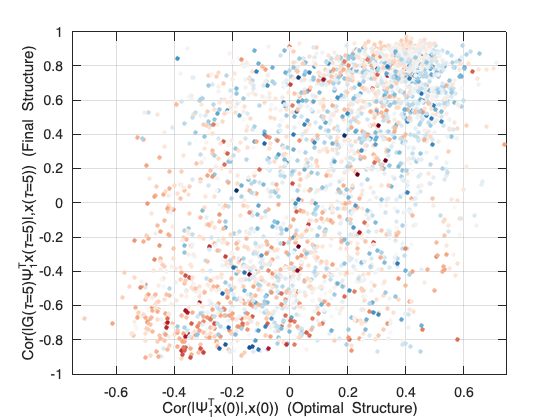

corOS  = NaN(length(x),1);
corFS  = NaN(length(x),1);
for k = 1:length(x)-(tau_m+1)

    tmp = nancorrcoef(x(k,:),optimStruct);
    corOS(k) = tmp(2);
    tmp = nancorrcoef(x(k+tau_m,:),Gt_taum*optimStruct);
    corFS(k) = tmp(2); 

end

clf;
cmap2 = (cbrewer('div', 'RdBu',50, 'linear'));
scatter(corOS,corFS,20,[0;movmean(diff(mean(x,2,'omitnan')),14)],'filled'); 
colormap(cmap2);
%plot(corOS,corFS,'o','markersize',6,'markerfacecolor',cmap(1,:),'markeredgecolor','k');         
xlabel('Cor(|\Psi_1^Tx(0)|,x(0)) (Optimal Structure)');
ylabel('Cor(|G(\tau=5)\Psi_1^Tx(\tau=5)|,x(\tau=5)) (Final Structure)');
grid on; xlim([-0.75 0.75]); set(gca,'xtick',-0.8:0.2:0.8);
%grid on; xlim([-1 1]); set(gca,'xtick',-1:0.2:1,'ytick',-1:0.2:1);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 14]);
box on; caxis([-0.25 0.25]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig5_optFin']); end 

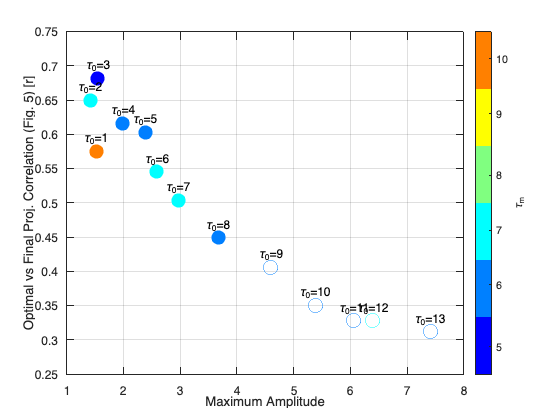

% these data calculated with removal of 1st, 2nd cycles. 2/19/25
am = [10,7,5,6,6,7,7,6,6,6,6,7,6];%,5,5]; % tau_m
ba = [1.52,1.42,1.55,1.99,2.39,2.59,2.97,3.67,4.60,5.38,6.06,6.39,7.41];%,15.65,20.00]; % maximum amplitude, first eigenval (ie @ tau_m)
cc = [0.5748,0.6494,0.6817,0.6164,0.6031,0.5454,0.5038,0.4486,0.4060,0.3499,0.3275,0.3274,0.3117];%,0.1915,0.1627]; % opt/fin correlations
dt = [1,2,3,4,5,6,7,8,9,10,11,12,13];%,14,15]; % specified tau_0

clf;
scatter(ba(1:8),cc(1:8),200,am(1:8),'o','filled'); box on; grid on; hold on;
scatter(ba(9:end),cc(9:end),200,am(9:end),'o'); 
colormap(jet(max(am)-min(am)+1));  h = colorbar; 
h.Ticks = [5.4 6.3 7.1 7.9 8.8 9.6];
h.TickLabels = {'5','6','7','8','9','10','11','12','13'};
h.Label.String = '\tau_m';
xlabel('Maximum Amplitude');
ylabel('Optimal vs Final Proj. Correlation (Fig. 5) [r]');
labelpoints(ba,cc,[{'\tau_0=1'} {'\tau_0=2'} {'\tau_0=3'} {'\tau_0=4'} {'\tau_0=5'} {'\tau_0=6'} ...
                   {'\tau_0=7'} {'\tau_0=8'} {'\tau_0=9'} {'\tau_0=10'} {'\tau_0=11'} {'\tau_0=12'} ...
                   {'\tau_0=13'}],'N',0.15,'FontSize',12)
ylim([0.25 0.75]);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 16]);
set(gca,'fontsize',12); if sav_fig == 1; print('-dpng','-r300',[fig_path,'Sup3.png']); end

**(2) Signal-to-Noise**

% trE from Eq. (9) of Newman et al. (2003) is already stored in epsilon(tau); we will use the unstandardized "raw" version  
trE = epsilon_raw(tau_0,:); 

% squared signal-to-noise, a f(tau,time)
S2 = NaN(length(Tau_arr),length(x));

% calculate S2 for each time
for j = 1:length(Tau_arr)

    % Subset xhat using chosen tau_0
    xhat = squeeze(fx_all(tau_0,j,:,:));

    for k = 1:length(x)

        F = trace((xhat(:,k).*xhat(:,k)')); 
        S2(j,k) = F ./ trE(j);

    end

end

% Eq. (7) from Newman et al. (2003)
rho_inf = S2 ./ ((S2+1).*S2).^0.5;

% rho_inf is f(t,Tau_arr) so (unlike optimProf), the optimal initial condition may be different at different lead times, though there is overlap
indgoodfx_rhoinf = [];
indgoodfx_rhoinf_val = [];
for k = 1:length(Tau_arr)
    indgoodfx_rhoinf = [indgoodfx_rhoinf; find(rho_inf(k,:) > prctile(rho_inf(k,:),66.66))];
    indgoodfx_rhoinf_val = [indgoodfx_rhoinf_val; find(rho_inf(k,validation_inds) > prctile(rho_inf(k,validation_inds),66.66))];
end

## VIII. Error Assessment

LIM skill is calculated using error variance, but we will also plot the unstandardized error ("raw"). Several other metrics will be shown, including calculating the error assuming persistence, a first-order autoregressive forecast, and the LIM's theoretical (expected) error,ε. Skill will also be shown for top-tercile optimal projections and *ρ∞*, as well as both positive and negative anomalies in ALBSA. The ALBSA anomalies are calculated usiing 1±σ thresholds. Note that the mean of ALBSA in winter is only marginally different than 0 and its distribution is approximately symmetrical with a skewness of 0.33.

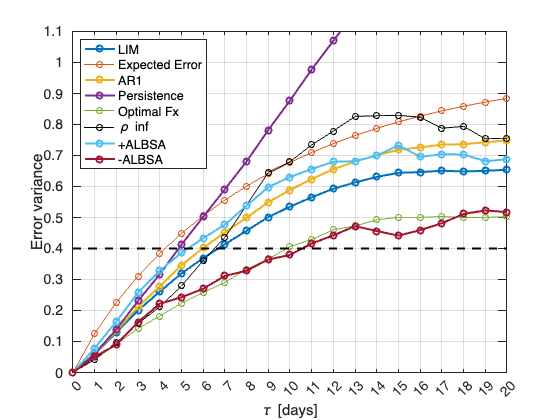

sigth = 1; % standard deviation threshold for anomaly 
indalbsap_val = find(albsalim(validation_inds)>(mean(albsalim,'omitnan')+sigth*std(albsalim,'omitnan')));
indalbsan_val = find(albsalim(validation_inds)<(mean(albsalim,'omitnan')-sigth*std(albsalim,'omitnan')));

xhat                     = squeeze(fx_all(tau_0,:,:,validation_inds))        ; % LIM forecast, xhat, using chosen tau0

% standardize errors
normErrLIM               = NaN(nDat,length(Tau_arr))           ; % standardized LIM error
normErrPers              = NaN(nDat,length(Tau_arr))           ; % standardized persistence error
ar1                      = NaN(nDat,length(Tau_arr))           ; % standardized 1st order autoregressive error
normErrLIMgoodfx_optprj  = NaN(nDat,length(Tau_arr))           ; % standardized LIM error based on optimal projection
normErrLIMgoodfx_rhoinf  = NaN(nDat,length(Tau_arr))           ; % standardized LIM error based on rho infinite
normErrLIMalbsapfx       = NaN(nDat,length(Tau_arr))           ; % standardized LIM error based on positive ALBSA
normErrLIMalbsanfx       = NaN(nDat,length(Tau_arr))           ; % standardized LIM error based on negative ALBSA

% as before, unstandardized
normErrLIMr              = NaN(nDat,length(Tau_arr))           ; % raw LIM error
normErrPersr             = NaN(nDat,length(Tau_arr))           ; % raw persistence error
ar1r                     = NaN(nDat,length(Tau_arr))           ; % raw 1st order autoregressive error
normErrLIMgoodfxr_optprj = NaN(nDat,length(Tau_arr))           ; % raw LIM error based on optimal projection
normErrLIMgoodfxr_rhoinf = NaN(nDat,length(Tau_arr))           ; % raw LIM error based on rho infinite
normErrLIMalbsapfxr      = NaN(nDat,length(Tau_arr))           ; % raw LIM error based on positive ALBSA
normErrLIMalbsanfxr      = NaN(nDat,length(Tau_arr))           ; % raw LIM error based on negative ALBSA

for k = 1:nDat

    for h = 1:length(Tau_arr)

        % Some values will be used more than once so calculate up front
        xobs = x(validation_inds,k);
        xvar = var(x(validation_inds,k),'omitnan');

        xobs_optprj = x(validation_inds(indgoodfx_optprj_val),k);
        xvar_optprj = var(x(validation_inds(indgoodfx_optprj_val),k),'omitnan');

        xobs_rhoinf = x(validation_inds(indgoodfx_rhoinf_val(h,:)),k);
        xvar_rhoinf = var(x(validation_inds(indgoodfx_rhoinf_val(h,:)),k),'omitnan');

        xobs_ap = x(validation_inds(indalbsap_val),k);
        xvar_ap = var(x(validation_inds(indalbsap_val),k),'omitnan');

        xobs_an = x(validation_inds(indalbsan_val),k);
        xvar_an = var(x(validation_inds(indalbsan_val),k),'omitnan');

        % Calculate standardized errors         
        normErrLIM(k,h) = var(squeeze(xhat(h,k,:))-xobs,'omitnan') / xvar; 
        normErrPers(k,h) = var(xobs(Tau_arr(h)+1:end)-xobs(1:end-Tau_arr(h)),'omitnan') / xvar; 
        aproc = exp((-1/sta_eF(k))*Tau_arr(h)) * xobs;
        ar1(k,h) = var(xobs(Tau_arr(h)+1:end) - aproc(1:end-Tau_arr(h)),'omitnan') / xvar; 
        normErrLIMgoodfx_optprj(k,h) = var(squeeze(xhat(h,k,indgoodfx_optprj_val))-xobs_optprj,'omitnan') / xvar_optprj; 
        normErrLIMgoodfx_rhoinf(k,h) = var(squeeze(xhat(h,k,indgoodfx_rhoinf_val(h,:)))-xobs_rhoinf,'omitnan') / xvar_rhoinf; 
        normErrLIMalbsapfx(k,h) = var(squeeze(xhat(h,k,indalbsap_val))-xobs_ap,'omitnan') / xvar_ap; 
        normErrLIMalbsanfx(k,h) = var(squeeze(xhat(h,k,indalbsan_val))-xobs_an,'omitnan') / xvar_an; 
        
        % Calculate unstandardized (raw) errors
        normErrLIMr(k,h) = var(squeeze(xhat(h,k,:))-xobs,'omitnan') / xvar; 
        normErrPersr(k,h) = var(xobs(Tau_arr(h)+1:end)-xobs(1:end-Tau_arr(h)),'omitnan'); 
        aprocr = exp((-1/sta_eF(k))*Tau_arr(h)) * xobs;
        ar1r(k,h) = var(xobs(Tau_arr(h)+1:end) - aproc(1:end-Tau_arr(h)),'omitnan'); 
        normErrLIMgoodfxr_optprj(k,h) = var(squeeze(xhat(h,k,indgoodfx_optprj_val))-xobs_optprj,'omitnan'); 
        normErrLIMgoodfxr_rhoinf(k,h) = var(squeeze(xhat(h,k,indgoodfx_rhoinf_val(h,:)))-xobs_rhoinf,'omitnan'); 
        normErrLIMalbsapfxr(k,h) = var(squeeze(xhat(h,k,indalbsap_val))-xobs_ap,'omitnan'); 
        normErrLIMalbsanfxr(k,h) = var(squeeze(xhat(h,k,indalbsan_val))-xobs_an,'omitnan'); 

    end

end

cmap = lines(256);
clf;
plot([0 Tau_arr],[0 mean(normErrLIM)],'ko-','color',cmap(1,:),'linewidth',2); hold on;
plot([0 Tau_arr],[0 epsilon(tau_0,:)],'ko-','color',cmap(2,:),'linewidth',1);
plot([0 Tau_arr],[0 mean(ar1)],'ko-','color',cmap(3,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrPers)],'ko-','color',cmap(4,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMgoodfx_optprj)],'ko-','color',cmap(5,:),'linewidth',1);
plot([0 Tau_arr],[0 mean(normErrLIMgoodfx_rhoinf)],'ko-','linewidth',1);
plot([0 Tau_arr],[0 mean(normErrLIMalbsapfx)],'ko-','color',cmap(6,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMalbsanfx)],'ko-','color',cmap(7,:),'linewidth',2);
grid on; hline(0.4); ylim([0 1.1]); xlim([0 20]);
set(gca,'ytick',0:0.1:1.1,'xtick',0:21);
xlabel('\tau [days]'); ylabel('Error variance'); 
grid on;
legend('LIM','Expected Error','AR1','Persistence','Optimal Fx','\rho inf','+ALBSA','-ALBSA','location','northwest');
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 30 18]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig6_meanerror1.png']); end

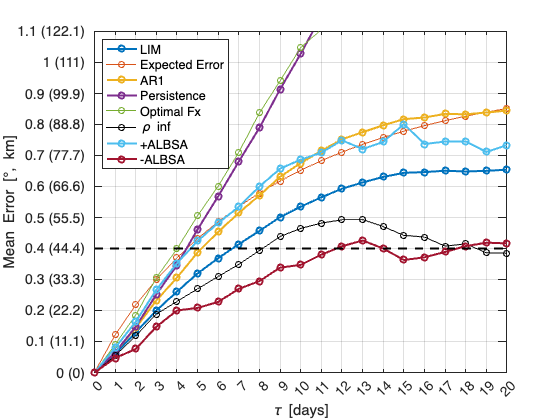

clf;
plot([0 Tau_arr],[0 mean(normErrLIMr)],'ko-','color',cmap(1,:),'linewidth',2); hold on;
plot([0 Tau_arr],[0 epsilon_raw(tau_0,:)],'ko-','color',cmap(2,:),'linewidth',1);
plot([0 Tau_arr],[0 mean(ar1r)],'ko-','color',cmap(3,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrPersr)],'ko-','color',cmap(4,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMgoodfxr_optprj)],'ko-','color',cmap(5,:),'linewidth',1);
plot([0 Tau_arr],[0 mean(normErrLIMgoodfxr_rhoinf)],'ko-','linewidth',1);
plot([0 Tau_arr],[0 mean(normErrLIMalbsapfxr)],'ko-','color',cmap(6,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMalbsanfxr)],'ko-','color',cmap(7,:),'linewidth',2);
tmp = 0:0.1:1.1;
ylabs = [];
for k = 1:length(tmp)
    ylabs = [ylabs; {[num2str(tmp(k)),' (',num2str(tmp(k)*111),')']}];
end
grid on; hline(0.4); ylim([0 1.1]); xlim([0 20]); 
set(gca,'ytick',0:0.1:1.1,'xtick',0:21,'yticklabel',ylabs);
xlabel('\tau [days]'); ylabel('Mean Error [\circ, km]'); 
%title('Fx Errors'); 
grid on;
legend('LIM','Expected Error','AR1','Persistence','Optimal Fx','\rho inf','+ALBSA','-ALBSA','location','northwest');
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 30 18]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig6_meanerrorraw1.png']); end

xx = 0:1/24:60;
YY = NaN(nDat,5);
for k = 1:nDat
    yy = interp1([0 Tau_arr],[0 normErrPers(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,1) = tmp;
    yy = interp1([0 Tau_arr],[0 ar1(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,2) = tmp;
    yy = interp1([0 Tau_arr],[0 normErrLIM(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,3) = tmp;  
    yy = interp1([0 Tau_arr],[0 normErrLIMgoodfx_optprj(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,4) = tmp;  
    yy = interp1([0 Tau_arr],[0 normErrLIMgoodfx_rhoinf(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,5) = tmp;  
end
eval(['YYrem',num2str(deseas),' = YY']); % eval...i know. my apologies.

YYrem2 =     3.7917    4.5833    4.9167   11.5000    3.3750
    3.2083    3.5833    3.5833    3.7917    2.6667
    3.0833    3.4583    3.7083    5.6667    3.5000
    3.2500    3.7083    3.7917    6.7917    4.6250
    3.7917    4.3333    4.5000    9.6250    5.6667
    4.2917    5.2917    5.2917   11.4167    5.8333
    5.2083    6.8333    7.8750   23.3750    7.6667
    5.2500    6.4167    7.6667   23.8333    7.6667
    5.5833    6.7917    8.0000   13.0833    8.6667
    5.4167    6.8750    7.9583   11.5417    7.2917


save([data_path,'rem',num2str(deseas),'.mat'], ['YYrem',num2str(deseas)]);

yy = interp1([0 Tau_arr],[0 mean(normErrPers)],xx);
disp(['Persistence skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 

Persistence skill at 0.4 ev = 4.875 days


yy = interp1([0 Tau_arr],[0 mean(ar1)],xx);
disp(['AR1 skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 

AR1 skill at 0.4 ev = 6 days


yy = interp1([0 Tau_arr],[0 mean(normErrLIM)],xx);
disp(['LIM skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 

LIM skill at 0.4 ev = 6.7083 days


yy = interp1([0 Tau_arr],[0 mean(normErrLIMgoodfx_optprj)],xx);
disp(['LIM optimal skill (projection) at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']);

LIM optimal skill (projection) at 0.4 ev = 9.875 days


yy = interp1([0 Tau_arr],[0 mean(normErrLIMgoodfx_rhoinf)],xx);
disp(['LIM optimal skill (\rho_i_n_f) at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']);

LIM optimal skill (\rho_i_n_f) at 0.4 ev = 6.5417 days


## IX. Case Study

Plot an example of the time series from the validation set in winter 2023.

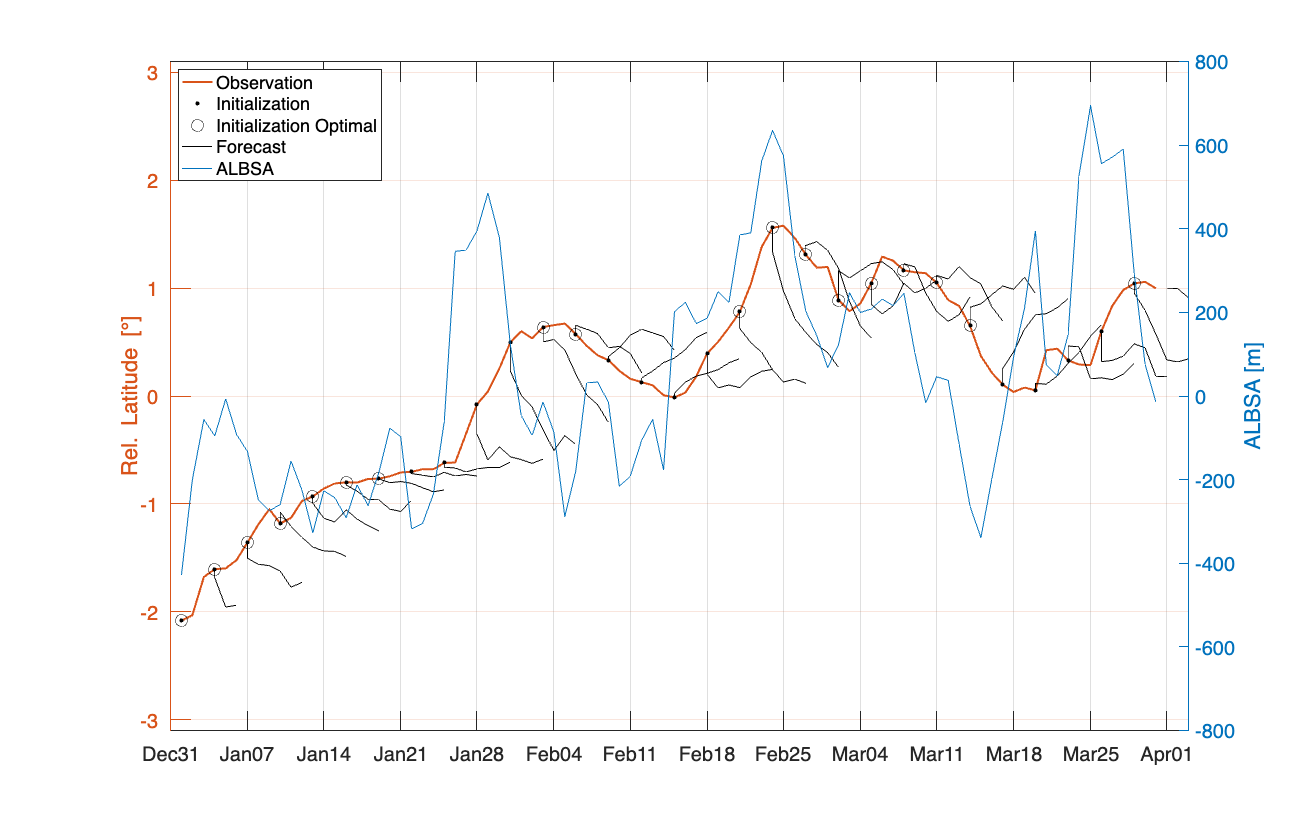

ind = find(yyyy == 2023);

thedata = mean(x(ind,:),2,'omitnan');

fx_all_case = squeeze(fx_all(tau_0,:,:,ind));

clf;
h1=plot(iceedge_dn(ind),thedata,'linewidth',2,'color',cmap(2,:)); hold on;

for initday = 1:3:length(ind)
    ds = [];
    val = [];
    for fxlead = 0:7      
        if fxlead == 0
            subi = ind(initday);
            ds = [ds; iceedge_dn(subi)];
            val = [val; thedata(initday)];
            if ismember(ind(initday),indgoodfx_optprj)
                h2b=plot(ds,val,'k.','markersize',12);
                h2a=plot(ds,val,'ko','markersize',12);
            else
                h2b=plot(ds,val,'k.','markersize',12);
            end
        else
            subi = ind(initday)+fxlead-1;
            if subi > length(iceedge_dn); continue; end
            ds = [ds; iceedge_dn(subi)];
            val = [val; mean(fx_all_case(fxlead,:,initday),'omitnan')];
        end
    end
    h3=plot(ds,val,'k-');
end
set(gca,'xtick',iceedge_dn(ind(1)-1):7:iceedge_dn(ind(1)+92));
xlim([iceedge_dn(ind(1)-1) iceedge_dn(ind(1)+92)]);
datetick('x','mmmdd','keepticks','keeplimits')
grid on;
ylabel('Rel. Latitude [\circ]');
ylim([-3.1 3.1]);
set(gca,'fontsize',20);

yyaxis right

h4=plot(iceedge_dn(ind),albsalim(ind),'linewidth',1,'color',cmap(1,:)); 
ylim([-800 800]);
ylabel('ALBSA [m]');

ax = gca;
ax.YAxis(1).Color = cmap(2,:);
ax.YAxis(2).Color = cmap(1,:);

legend([h1 h2b h2a h3 h4],'Observation','Initialization','Initialization Optimal', ...
    'Forecast','ALBSA','location','northwest');

set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 40 18]);
set(gca,'fontsize',20); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig7_casestudy_west']); end

## X. ALBSA maps

Plot the GPH for +ALBSA and -ALBSA scenarios that were tested earlier.

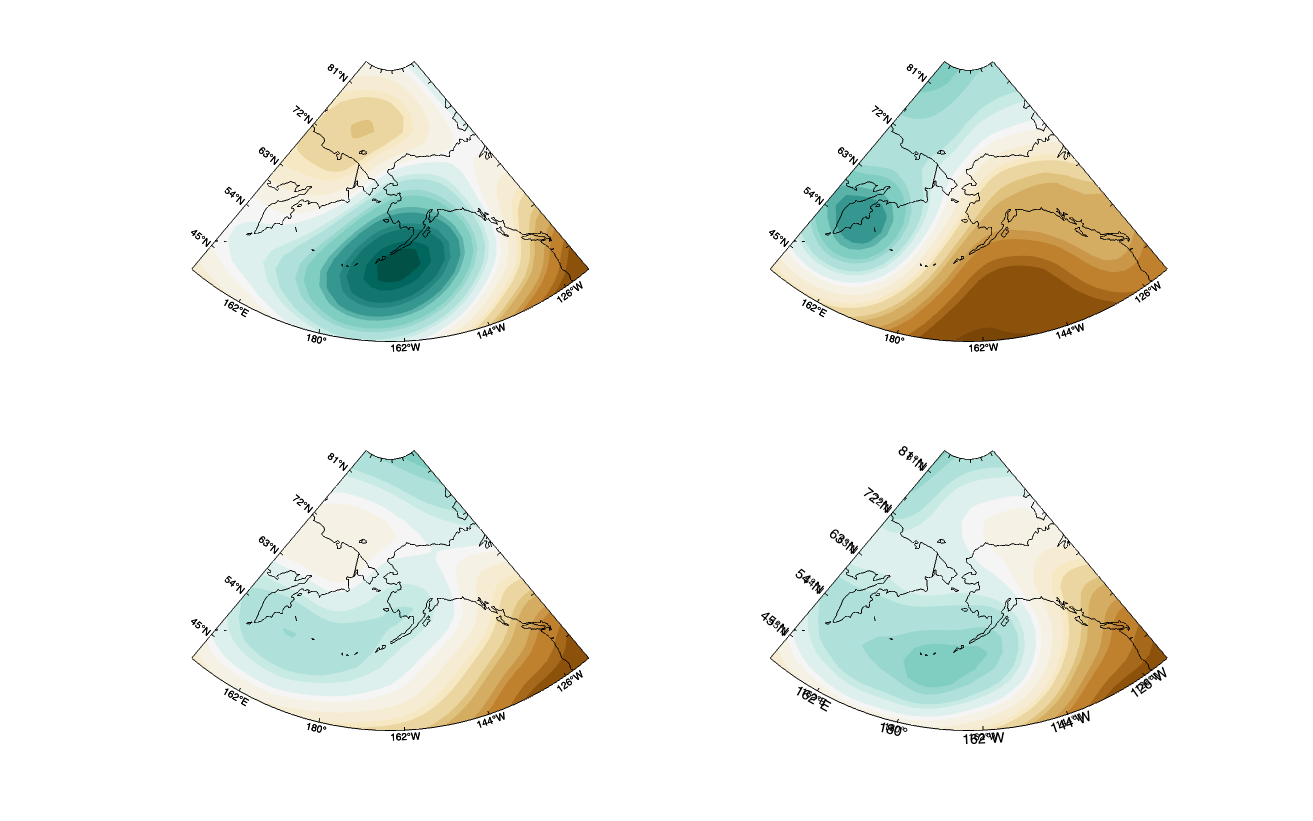

indalbsap = find(albsalim>(mean(albsalim,'omitnan')+sigth*std(albsalim,'omitnan')));
indalbsan = find(albsalim<(mean(albsalim,'omitnan')-sigth*std(albsalim,'omitnan')));

indalbsap_val = find(albsalim(validation_inds)>(mean(albsalim,'omitnan')+sigth*std(albsalim,'omitnan')));
indalbsan_val = find(albsalim(validation_inds)<(mean(albsalim,'omitnan')-sigth*std(albsalim,'omitnan')));

subplot(2,2,1)
cmap = flipud(cbrewer('div', 'BrBG',nDato, 'linear'));
m_proj('lambert','long',[150 240],'lat',[40 85]);
    [C,dummy] = m_contourf(repmat(albsa.lon,1,length(albsa.lat)), ...
        repmat(albsa.lat,1,length(albsa.lon))',squeeze(mean(amap(:,:,indalbsan),3,'omitnan')),1150:10:1550,'edgecolor','none');
m_coast('linewidth',0.5,'color','k');
hold on; m_grid('linestyle','none','tickdir','in','linewidth',1);  
caxis([1150 1550]);
colormap(cmap)
subplot(2,2,2)
cmap = flipud(cbrewer('div', 'BrBG',nDato, 'linear'));
m_proj('lambert','long',[150 240],'lat',[40 85]);
    [C,dummy] = m_contourf(repmat(albsa.lon,1,length(albsa.lat)), ...
        repmat(albsa.lat,1,length(albsa.lon))',squeeze(mean(amap(:,:,indalbsap),3,'omitnan')),1150:10:1550,'edgecolor','none');
m_coast('linewidth',0.5,'color','k');
hold on; m_grid('linestyle','none','tickdir','in','linewidth',1);  
caxis([1150 1550]);
colormap(cmap)
subplot(2,2,3)
cmap = flipud(cbrewer('div', 'BrBG',nDato, 'linear'));
m_proj('lambert','long',[150 240],'lat',[40 85]);
    [C,dummy] = m_contourf(repmat(albsa.lon,1,length(albsa.lat)), ...
        repmat(albsa.lat,1,length(albsa.lon))',squeeze(mean(amap(:,:,indalbsan_val),3,'omitnan')),1150:10:1550,'edgecolor','none');
m_coast('linewidth',0.5,'color','k');
hold on; m_grid('linestyle','none','tickdir','in','linewidth',1);  
caxis([1150 1550]);
colormap(cmap)
subplot(2,2,4)
cmap = flipud(cbrewer('div', 'BrBG',nDato, 'linear'));
m_proj('lambert','long',[150 240],'lat',[40 85]);
    [C,dummy] = m_contourf(repmat(albsa.lon,1,length(albsa.lat)), ...
        repmat(albsa.lat,1,length(albsa.lon))',squeeze(mean(amap(:,:,indalbsap_val),3,'omitnan')),1150:10:1550,'edgecolor','none');
m_coast('linewidth',0.5,'color','k');
hold on; m_grid('linestyle','none','tickdir','in','linewidth',1);  
caxis([1150 1550]);
colormap(cmap)
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 34 20]);
set(gca,'fontsize',14); if sav_fig == 1; print('-dpng','-r300',[fig_path,'fig8_albsamaps']); end